clear all
close all
clc

load intrinsic.mat
load checkerboard_points.mat

对比自己的和官方代码的差异

Kc = cameraParams4.Intrinsics.IntrinsicMatrix';
D = cat(2,cameraParams4.Intrinsics.RadialDistortion, cameraParams4.Intrinsics.TangentialDistortion);
points_u_my = undistortPoints_my(imagePoints1, Kc, D)

points_u_my = 1.0e+03 *

    1.4243    0.2334
    1.4196    0.2015
    1.4148    0.1695
    1.4100    0.1374
    1.4050    0.1047
    1.4000    0.0721
    1.3950    0.0393
    1.3898    0.0064
    1.3976    0.2382
    1.3927    0.2061


points_u_official = undistortPoints(imagePoints1,cameraParams4)

points_u_official = 1.0e+03 *

    1.4250    0.2329
    1.4204    0.2008
    1.4157    0.1686
    1.4112    0.1363
    1.4064    0.1033
    1.4016    0.0703
    1.3969    0.0370
    1.3921    0.0034
    1.3981    0.2378
    1.3933    0.2056


I = imread('D:\Projects\LineStructureLightCalib\data\checkerboard_light_selected\2023-01-17_13_55_34_404.bmp');
[J, newOrigin] = undistortImage(I,cameraParams4,'OutputView','full');

undistortedPoints = [points_u_official(:,1) - newOrigin(1), ...
                    points_u_official(:,2) - newOrigin(2)];

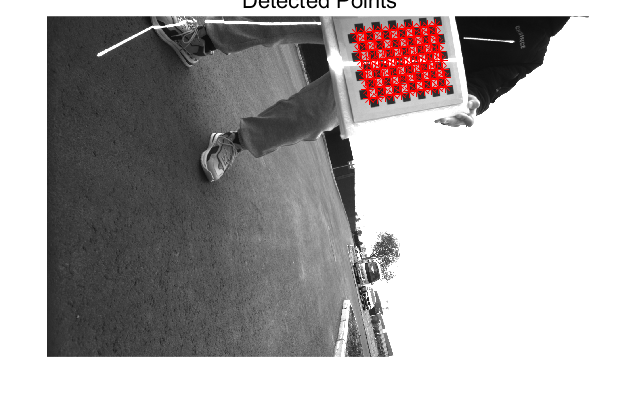

figure; 
imshow(I); 
hold on;
plot(imagePoints1(:,1),imagePoints1(:,2),'r*-');
title('Detected Points'); 
hold off;

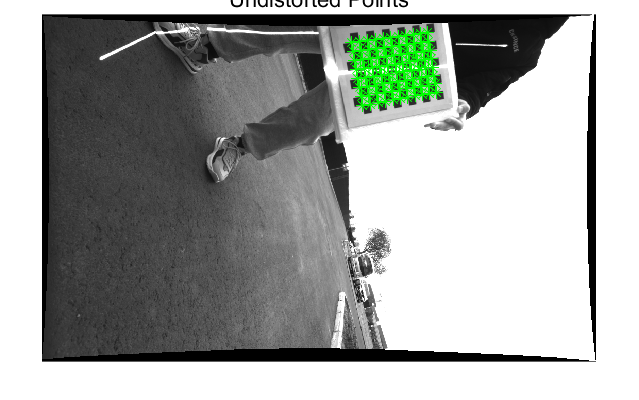


figure; 
imshow(J); 
hold on;
plot(undistortedPoints(:,1),undistortedPoints(:,2),'g*-');
title('Undistorted Points'); 
hold off;